%{
% genFunctions.m
% Script that when we run, it generates our functions
% that return our cost and constraint matrices/vectors
% We should only need to run this every time we
% change the problem
% Christian Hubicki
clc
clear
close all
N = 21; % Number of nodes
% Create our state and input vectors symbolically
q = sym('q',[5 1])
u = sym('u',[2 1])
% Operating point
p = sym('p',[5 1])
% Linearized Dynamics
TauLim = 0.5;
distLim = 0.5;

R = 0.1; % Radius of wheels
L = 0.5; % Distance between wheels
m = 5; % Mass of robot
D = 0; % COM from robot base frame origin
J = 2; % Intertia about COM
b = 1; % ?

q_dot = [q(3)*cos(q(4));
         q(3)*sin(q(4));
         d*q(5)^2 + (u(2) + u(1))/(M*R) - b*q(3);
         q(5);
         L/(M*d^2 + J) * (u(2) - u(1))/R - M*d/(M*d^2 + J) * q(3)*q(5)];

A = jacobian(q_dot, q);
B = jacobian(q_dot, u);
matlabFunction(A, 'File', 'A_matrix.m', 'Vars', {q,u});
matlabFunction(B, 'File', 'B_matrix.m', 'Vars', {q,u});
% genFunctions.m
% Script that when we run, it generates our functions
% that return our cost and constraint matrices/vectors
% We should only need to run this every time we
% change the problem
% Christian Hubicki
clc
clear
close all
N = 21; % Number of nodes
% Create our state and input vectors symbolically
q = sym('q',[4 1])
u = sym('u',[2 1])
% Dynamics
m = 1;
A = [0 1 0 0; 0 0 0 0; 0 0 0 1; 0 0 0 0]
B = [0 0; 1/m 0; 0 0; 0 1/m]
% Dynamics
dq = A*q+B*u
% Define symbolic variables for every state at each node and each input
qN = sym('qN',[4 N])
uN = sym('uN',[2 N])
% 1st-order Dynamics for each of the states at each node
dqN = A*qN+B*uN
% Defect constraints
% Explicit Euler
syms T % Constant finite time horizon
dt = T/(N-1); % Time between nodes
qNext = qN(:,2:end)
qPrev = qN(:,1:end-1)
dqPrev = dqN(:,1:end-1)
defect = qNext - qPrev - dqPrev*dt
defect = defect(:)
syms Fmax % Max force
q0 = sym('q0',[4 1])
% IC constraints
ic_constraint = q0-qN(:,1)
% Inequality
limit_constraints = [uN(:) - Fmax; -uN(:) - Fmax]
eqCon = [defect; ic_constraint]
ineqCon = limit_constraints
% Cost Function
Q = sym('Q',[4 4])
R = sym('R',[2 2])
qdes = sym('qdes',[4 1])
% Define our cost
cost = sum(sum((((qdes-qN(:,1:end-1)).'*Q*(qdes-qN(:,1:end-1)) + ...
uN(:,1:end-1).'*R*uN(:,1:end-1)))*dt))
% Decision vector
x = [uN(:); qN(:)]
% Cost
H = hessian(cost,x)
c = subs(jacobian(cost,x),x,zeros(size(x))).'
% Constraints
A = jacobian(ineqCon,x)
b = -subs(ineqCon,x,zeros(size(x)))
Aeq = jacobian(eqCon,x)
beq = -subs(eqCon,x,zeros(size(x)))
% Export MATLAB Functions
matlabFunction(H,'File','Hfunc','Vars',{Q,R,qdes,T})
matlabFunction(c,'File','cfunc','Vars',{Q,R,qdes,T})
matlabFunction(A,'File','Afunc','Vars',{T,Fmax})
matlabFunction(b,'File','bfunc','Vars',{T,Fmax})
matlabFunction(Aeq,'File','Aeqfunc','Vars',{q0,T,Fmax})
matlabFunction(beq,'File','beqfunc','Vars',{q0,T,Fmax}
%}

[ts, q_all, tauL, tauR] = run_MPC(ones(5,5),ones(2,2), 5);


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because

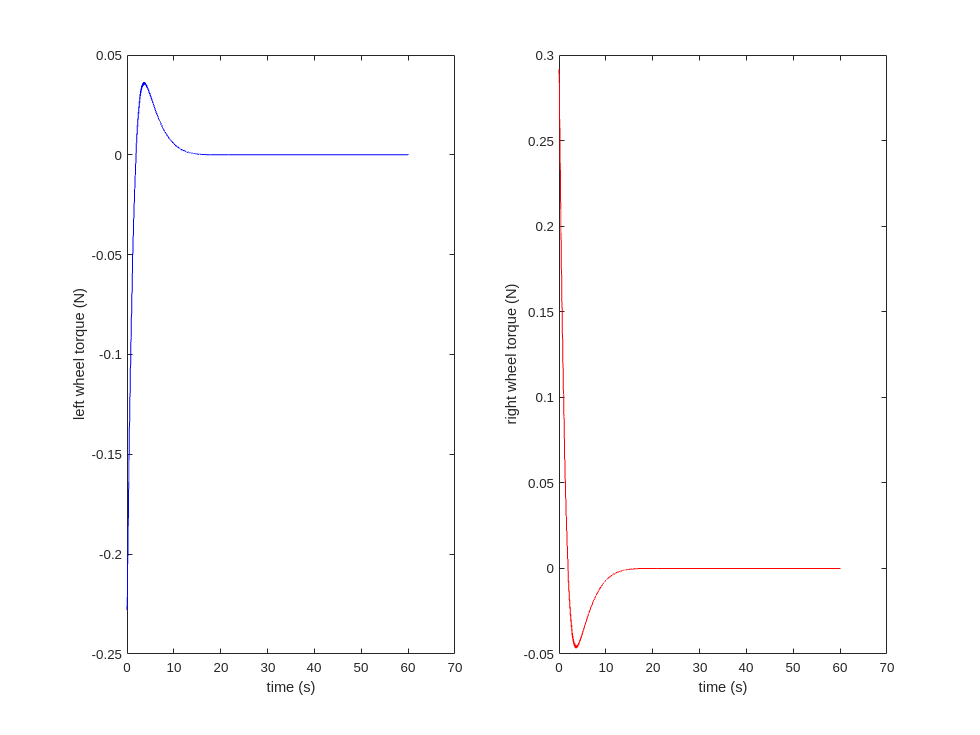


figure
hold on
subplot(1, 2, 1);
plot(ts, tauL, 'b-');
xlabel("time (s)")
ylabel("left wheel torque (N)")

subplot(1, 2, 2);
plot(ts, tauR, 'r-');
xlabel("time (s)")
ylabel("right wheel torque (N)")
hold off

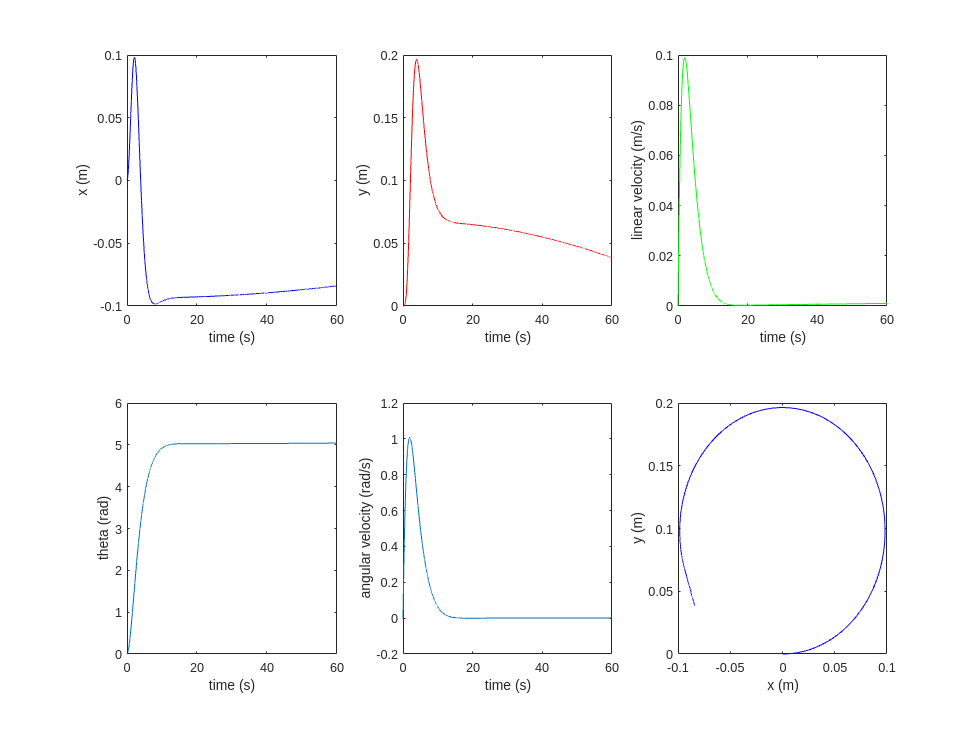


figure
hold on
subplot(2, 3, 1);
plot(ts, q_all(:,1), 'b-');
xlabel("time (s)")
ylabel("x (m)")

subplot(2, 3, 2);
plot(ts, q_all(:,2), 'r-');
xlabel("time (s)")
ylabel("y (m)")

subplot(2, 3, 3);
plot(ts, q_all(:,3), 'g-');
xlabel("time (s)")
ylabel("linear velocity (m/s)")

subplot(2, 3, 4)
plot(ts, q_all(:,4))
xlabel("time (s)")
ylabel("theta (rad)")

subplot(2, 3, 5);
plot(ts, q_all(:,5))
xlabel("time (s)")
ylabel("angular velocity (rad/s)")

subplot(2, 3, 6);
plot(q_all(:,1), q_all(:,2), 'b-');
xlabel("x (m)")
ylabel("y (m)")
hold off

animate_mpc(ts,q_all);

Unrecognized function or variable 'qs'.

function [t_all, q_all, torque_L, torque_R] = run_MPC(Q, R, T)
    % Define our Parameters
    q0 = [0;0;0;0;0]; % Initial state
    qdes = [5;0;0;0;0]; % Desired state
    
    % Q = zeros(2,2);
    Tmax = 5; % Maximum torque
    
    % dynamics variables 
    uo = zeros(2,1);
    qo = zeros(5,1);
    
    Amat = A_matrix(qo, uo);
    Bmat = B_matrix(qo, uo);
    
    % Simulation and MPC Control Loop 
    % quick simulation test
    % u = [1];
    % odefunparam = @(t,q) odefun(t,q,u);
    % [tout, qout] = ode45(odefunparam, [0 10], q0); % IT WORKS
    
    Tfinal = 60;
    Ts = 0.1;
    
    t_sim = 0:Ts:Tfinal;
    
    t_all = [];
    q_all = [];
    torque_L = [];
    torque_R = [];
    
    for iter = 1:numel(t_sim)
    
        % Step 1: Sample the current state
        % It's q0
    
    
        % Step 2: Formulate and Run the trajectory optimization
        % Define our Matrices/vectors for a QP
        H = Hfunc(Q,R,qdes,T);
        c = cfunc(Q,R,qdes,T);
        A = Afunc(T,Tmax);
        b = bfunc(T,Tmax);
        Aeq = Aeqfunc(q0,T,Tmax);
        beq = beqfunc(q0,T,Tmax);
        
        xstar = quadprog(H,c,A,b,Aeq,beq);
    
        % Step 3: Apply the optimal control inputs for Ts seconds 
        N = 21;
        u = xstar(1:2*N); % Torque over time
        uL = xstar(1:2:2*N-1);
        uR = xstar(2:2:2*N);
    
        r = 0.1; % Radius of each wheel
        L = 0.5; % Distance between wheels
        M = 5;
        d = 0;
        J = 2;
        b = 1;
    
        % have x = angular velocity spline? x = [vl1, ... vln, vr1, ... vrn, tf];
        interp_t_l = @(t) interp1(linspace(0, T, numel(uL)), uL, t);
        interp_t_r = @(t) interp1(linspace(0, T, numel(uR)), uR, t);
    
        odefun = @(t, y) odefun_torque(y, [interp_t_l(t); interp_t_r(t)], L, M, d, J, r, b);
        [tout, qout] = ode45(odefun,[0 Ts],q0);
    
        t_all = [t_all; tout+t_sim(iter)];
        q_all = [q_all; qout];
        size_tout = size(tout);
        torque_L = [torque_L; interp1(linspace(0,T,N),uL,tout)];
        torque_R = [torque_R; interp1(linspace(0,T,N),uR,tout)];
    
    
        % NOW Sample the current state:
        q0 = qout(end,:).';
    
    end
end